# Maze Solving using Value Iterations

## Maze Enviornment

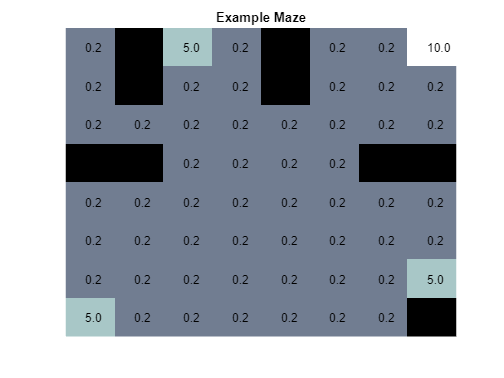

clear;clc;
R=0.2*ones(8,8);
n=length(R);

nStates=64;
nActions=4;
% Goal
R(1,8)=10;

% Other flags
R(1,3)=5;
R(7,8)=5;
R(8,1)=5;


% Void
R(1,2)=-10;
R(2,2)=-10;
R(4,1)=-10;
R(4,2)=-10;
R(1,5)=-10;
R(2,5)=-10;
R(4,7)=-10;
R(4,8)=-10;
R(8,8)=-10;

% True Transition Probability
T_True = zeros(nStates,nStates,nActions);
% Up
T_True(:,:,1) = 0.25* ones(nStates);
% Right
T_True(:,:,2) =  0.25*ones(nStates);
% Down
T_True(:,:,3) = 0.25* ones(nStates);
% Left
T_True(:,:,4) =  0.25*ones(nStates);

figure
matrixPlot(R)
title('Example Maze')

## Bayesian Reinforcement Learning

% Thamson Sampling
[Policy, Q]= Final_MazeSolver(nStates, nActions, R, T_True);%initializing
n_samples = 10;
for s = 1:nStates
    for a = 1:nActions
        % Each with normal distribution
        Priors{a,s} = ones(1,64);
    end
end

S=1;

for Episode=1:10
    Episode
    samples = zeros(nStates,nStates,nActions,n_samples);
    for s = 1:nStates
        for a = 1:nActions
            prior = Priors{a,s};
            samples(s,:,a,:) = drchrnd(prior, n_samples)';
        end
    end
    % Samples(:,:,:,1);
    % Get average Q table
    Q_all = zeros(8,8);
    for n = 1:n_samples
        T = samples(:,:,:,n);
        [~, Q]= Final_MazeSolver(nStates, nActions, R, T);
        Q_all = Q_all + Q;
    end
    Q_all=Q_all/n_samples;
    %Find policy
    Policy=FindPolicy(Q_all);
    [x, y] = ind2sub([8, 8], S);
    % Transition to the next state
    pdf = T_True(S, :, Policy(x,y));
    cdf = cumsum(pdf);
    r = rand(1); % sample an uniform prob
    S_prime = find(r<cdf,1,'first');
    
    Priors{Policy(x,y),S}(S_prime) = Priors{Policy(x,y),S}(S_prime) + 1;
    S = S_prime;
end

Episode = 1

Episode = 2

Episode = 3

Episode = 4

Episode = 5

Episode = 6

Episode = 7

Episode = 8

Episode = 9

Episode = 10

## Representing Policy

Tstr=string(Policy);
for i=1:8
    for j=1:8
        if Policy(i,j)==1
            Tstr(i,j)='\uparrow';
        elseif Policy(i,j)==2
            Tstr(i,j)='\rightarrow';
        elseif Policy(i,j)==3
            Tstr(i,j)='\downarrow';
        elseif Policy(i,j)==4
            Tstr(i,j)='\leftarrow';
        end
    end
end

Tstr(1,1)='Start';Tstr(1,3)='Flag';Tstr(7,8)='Flag';Tstr(8,1)='Flag';
Tstr(1,8)='Goal';Tstr(1,2)='';
Tstr(4,7)='';Tstr(2,2)='';Tstr(4,8)='';
Tstr(2,5)='';Tstr(4,1)='';
Tstr(1,5)='';Tstr(4,2)='';Tstr(8,8)='';

## Solved Maze

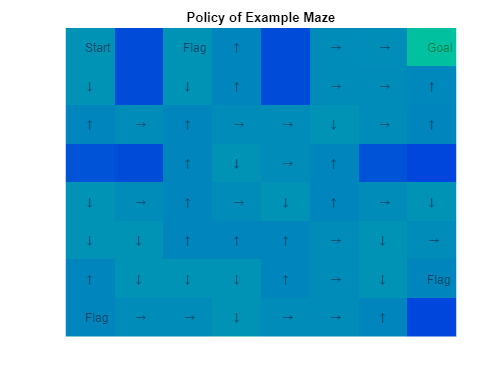

figure
imagesc(Policy)
colormap(white);

% Create x and y coordinates for the strings
[x,y] = meshgrid(1:length(Policy));

% Remove any space padding
Tstr= strtrim(cellstr(Tstr));

% Plot the strings
text(x(:)-0.1,y(:),Tstr(:));

title('Policy of Example Maze')
axis off

hold on
imagesc(Q_all,'AlphaData',0.5)
colormap(winter)
hold off

function r = drchrnd(a,n)
% take a sample from a dirichlet distribution
p = length(a);
r = gamrnd(repmat(a,n,1),1,n,p);
r = r ./ repmat(sum(r,2),1,p);
end
